clc
clear;

%%%%%%SELECT OPTIONS:
problem_num = 6; %{1, 2, 3, 4, 5, 6, 7}
diff_opt = "forward"; %{forward, backward, centered}
partition_opt = "full"; %{full, partition}

%%%%%%SET UP NEURAL NETWORK
%(1) Set up initial conditions and solve ODE:
function [C, t, h, arraySize, num_outputs, occurences] = probsetup(problem_num)
    if problem_num == 1
        occurences = 100; num_outputs = 4;
        c0 = [4.0; 1.0; 0.5; 0.0]; %initial condition
        tspan = linspace(0, 2, occurences); %constant time step
        h = 2/occurences;
        arraySize = [24 12 4];
        
        k1 = 5.7; k2 = 6.1; 
        dCdt = @(t, C) [ %setup ODE
            -k1 * C(1)
             k2 * C(1) - k2 * C(2)
             k2 * C(2)
             k1 * C(1) + k2 * C(2)
        ];
    elseif problem_num == 2
        occurences = 100; num_outputs = 3;
        c0 = [10.0; 5.0; 0.0]; %initial condition
        tspan = linspace(0, 1, occurences);
        h = 1/occurences;
        arraySize = [6 3];

        k1 = 4; k2 = 2; k3 = 40; k4 = 20;
        dCdt = @(t, C) [
            -k1*C(1) + k2*C(2)
             k1*C(2) - (k2 + k3)*C(2) + k4*C(3)
            -k4*C(3) + k3*C(2)
        ];
    elseif problem_num == 3
        occurences = 100; num_outputs = 2;
        c0 = [10.0; 5.0]; %initial condition
        tspan = linspace(0, 1, occurences);
        h = 1/occurences;
        arraySize = [6 3];

        k1 = 12.2; k2 = 7.97; k3 = 2.22;
        dCdt = @(t, C) [
            -(k1 + k3)*(C(1).^2)
            k1*(C(1).^2) - k2*(C(2))
        ];
    elseif problem_num == 4
        occurences = 100; num_outputs = 2;
        c0 = [1.2; 1.1]; %initial condition
        tspan = linspace(0, 1, occurences);
        h = 1/occurences;
        arraySize = [24 15 8 2];

        k1 = 3.24; k2 = 0.92;
        dCdt = @(t, C) [
            -k1*C(1)*(1 - C(2))
             k2*C(2)*(C(1) - 1)
        ];
    elseif problem_num == 5
        occurences = 100; num_outputs = 3;
        c0 = [1.0; 0.0; 0.0]; %initial condition
        tspan = linspace(0, 1, occurences);
        h = 1/occurences;
        arraySize = [6 3];

        k1 = 5.24; k2 = 1.21;
        dCdt = @(t, C) [
            -(2*k1 - (k1*C(2))/(k2*C(1) + C(2))) * C(1)
             (k1*C(1)*(k2*C(1) - C(2)))/(k2*C(1) + C(2))
             (k1*C(1)*C(2))/(k2*C(1) + C(2))
        ];
    elseif problem_num == 6
        occurences = 100; num_outputs = 3;
        c0 = [0.09; 0.09; 0.0]; %initial condition
        tspan = linspace(0, 1, occurences);
        h = 1/occurences;
        arraySize = [6 3];

        dCdt = @(t, C) [
            -(C(1) + 0.25) + (C(2) + 0.5) * exp((25*C(1))/(C(1) + 2))
            0.5 - C(2) - (C(2) + 0.5) * exp((25*C(1))/(C(1) + 2))
            C(1)^2 + C(2)^2 + 0.1
        ];
    elseif problem_num == 7
        occurences = 1000; num_outputs = 3;
        c0 = [10.0; 5.0; 1.0]; %initial condition
        tspan = linspace(0, 2, occurences);
        h = 1/occurences;
        arraySize = [120 36 18 9];

        dCdt = @(t, C) [
            (C(1) + 0.25) - sin(C(3))
            0.5 - C(2) * cos(C(1))
            C(1)^2 + sin(C(3))
        ];
    end %if 
    [t, C] = ode45(dCdt, tspan, c0); %solve ODE
end %function 

%(2) Calculate dX/dt
function [Xout, dXdt, dt] = diffmethod(Xin, t, h, diff_opt)
    if diff_opt == "forward"
        dXdt = (Xin(2:end,:) - Xin(1:end-1,:))/h; 
        Xout = Xin(1:end-1,:);
        dt = t(2:end) - t(1:end-1);
    elseif diff_opt == "backward"
        dXdt = (Xin(2:end,:) - Xin(1:end-1,:))/h;
        Xout = Xin(2:end,:);
        dt = t(2:end) - t(1:end-1);
    elseif diff_opt == "centered"
        dXdt = (Xin(3:end,:) - Xin(1:end-2,:))/(2*h);
        Xout = Xin(2:end-1,:);
        dt = (t(3:end) - t(1:end-2))/2;
    end %if 
end %function 

%(3) Train model to map x -> dx/dt
function [modelNN2, lossNN2] = trainNN(X, Y, arraySize, partition_opt)
    rng("default") 
    c = cvpartition(length(Y),"Holdout",0.20);
    trainingIdx = training(c); 
    XTrain = X(trainingIdx,:);
    YTrain = Y(trainingIdx,:);
    testIdx = test(c);
    XTest = X(testIdx,:);
    YTest = Y(testIdx,:);
    
    if partition_opt == "full"
        modelNN2 = fitrnet(X,Y,"Standardize",false, ...
            "LayerSizes", arraySize);
    elseif partition_opt == "partition"
        modelNN2 = fitrnet(XTrain,YTrain,"Standardize",false, ...
            "LayerSizes", arraySize);    
    end %if 
    lossNN2 = loss(modelNN2, XTest, YTest);
end %function 

[C, t, h, arraySize, num_outputs, occurences] = probsetup(problem_num);
[X, Y, dt] = diffmethod(C, t, h, diff_opt);
[modelNN2, lossNN2] = trainNN(X, Y, arraySize, partition_opt)

modelNN2 =   RegressionNeuralNetwork
             ResponseName: {'y1'  'y2'  'y3'}
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 99
               LayerSizes: [6 3]
              Activations: 'relu'
    OutputLayerActivation: 'none'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [1000×7 table]


  Properties, Methods


lossNN2 = 0.0016

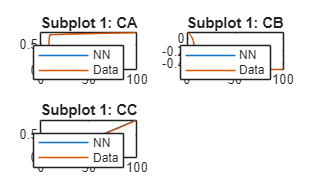


%%%%%%RESULT VALIDATION: Explicit Euler:
%(1) Calculate f'(x) using NN
fNN = zeros(occurences-1, num_outputs);
fNN(1:3, :) = C(1:3, :);
for i = 2:(occurences-2)
    fNN(i+1,:) = fNN(i,:) + dt(i) .* predict(modelNN2, fNN(i,:));
end %for

%(2) Plot to check results (Raw data vs NN)
figure
hold on
% set(gcf,'Visible','on')
if num_outputs == 4 || num_outputs == 3
    p = tiledlayout(2,2);
    ptitles = ['Subplot 1: CA'
        'Subplot 1: CB'
        'Subplot 1: CC'  
        'Subplot 1: CD'];
elseif num_outputs == 2
    p = tiledlayout(1,2);
    ptitles = ['Subplot 1: CA'
        'Subplot 1: CB'];
end %if 
for i = 1:num_outputs
    nexttile;
    plot([fNN(1:(occurences-1),i), C(1:occurences-1,i)])
    legend('NN', 'Data')
    title(ptitles(i, :))
end 
hold off

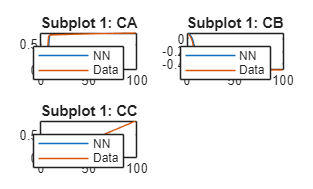


%%%%%%RESULT VALIDATION: FORWARD PASS:
%(1) Calculate f'(x) using NN
fNN = zeros(occurences-1, num_outputs);
fNN(1, :) = C(1, :);
numLayers = size(arraySize, 2);
for i = 1:(occurences-1)
    zk = fNN(i, :)';
    for j = 1:numLayers
        zk = modelNN2.LayerWeights{j} * zk + modelNN2.LayerBiases{j};
        zk = max(0, zk);
    end %for
    zk = modelNN2.LayerWeights{numLayers+1} * zk + modelNN2.LayerBiases{numLayers+1};
    
    fNN(i+1, :) = fNN(i, :) + dt(i) .* zk';
end %for 

%(2) Plot to check results (Raw data vs NN)
figure
hold on
% set(gcf,'Visible','on')
if num_outputs == 4 || num_outputs == 3
    p = tiledlayout(2,2);
    ptitles = ['Subplot 1: CA'
        'Subplot 1: CB'
        'Subplot 1: CC'  
        'Subplot 1: CD'];
elseif num_outputs == 2
    p = tiledlayout(1,2);
    ptitles = ['Subplot 1: CA'
        'Subplot 1: CB'];
end %if 
for i = 1:num_outputs
    nexttile;
    plot([fNN(1:(occurences-1),i), C(2:occurences,i)])
    legend('NN', 'Data')
    title(ptitles(i, :))
end 
hold off

%%%%%%STORE RAW DATA
filename = "FitRNet_Storage_RawData.xlsx";
writematrix(C, filename,'Sheet', 1, 'Range', 'A1')
writematrix(t, filename,'Sheet', 2, 'Range', 'A1')


%%%%%%STORE NN COEFFICIENTS DATA
filename = "FitRNet_Storage_THETA.xlsx";
for i = 1:length(modelNN2.LayerSizes)+1
    writematrix(modelNN2.LayerWeights{i}, filename,'Sheet', i, 'Range', 'A1')
end %for 

filename = "FitRNet_Storage_CCOEFF.xlsx";
for i = 1:length(modelNN2.LayerSizes)+1
    writematrix(modelNN2.LayerBiases{i}, filename,'Sheet', i, 'Range', 'A1')
end %for 